# SISO

% load("results\shin_siso.mat");
% 常用参数
legend_name = {'true', 'd-ISIM (full)', 'd-ISIM (reduce)', 'IV4', 'SIM (time)', 'SIM (freq)'};
font_size = 10; line_width = 1.5;

scatter

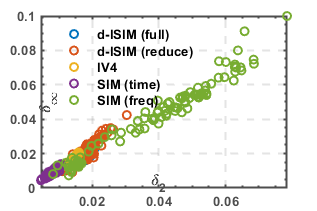

fig = figure; ax = axes(fig); 
set(gcf, 'Units', 'centimeters'); set(gcf, 'Position', [0, 0, 15, 10]);
% scatter
scatter(ax, analy_h2.', analy_hinf.', LineWidth=line_width);
legend(ax, legend_name(2:end), FontName = 'Arial', FontSize=font_size, FontWeight='bold', Location='northwest', Box='off');
% 坐标轴
Xlm = xlim; Ylm = ylim;  % get x, y axis limits, so can position relative instead of absolute
xlabel(ax, '\delta_2', Position=[mean(Xlm) 0.10*diff(Ylm)], FontSize=font_size+2, FontWeight='bold', FontName='Arial');
ylabel(ax, '\delta_\infty', Position=[0.12*diff(Xlm) mean(Ylm)], FontSize=font_size+2, FontWeight='bold', FontName='Arial');
% decoration
betterFig(fig, font_size, line_width);
exportgraphics(fig, 'results\siso_scatter.eps')

# MIMO

% load("results\shin_mimo.mat");
% 常用参数
legend_name = {'als (new)', 'als (kalman)', 'innovation'};
font_size = 10; line_width = 1.5;

covariance

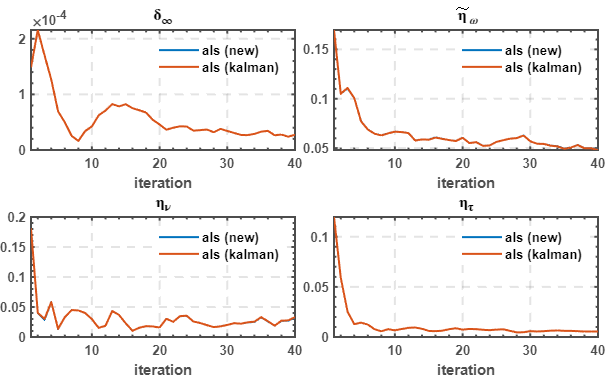

fig = figure; tl = tiledlayout(2, 2, 'TileSpacing', 'tight', 'Padding', 'tight');
set(gcf, 'Units', 'centimeters'); set(gcf, 'Position', [0, 0, 16, 10]);
% h_inf
ax = nexttile;
plot(ax, analy_hinf(1:2, :).');
legend(ax, legend_name(1:2), FontName = 'Arial', FontSize=font_size, FontWeight='bold', Location='northeast', Box='off');
xlabel(ax, 'iteration', FontSize=font_size, FontWeight='bold', FontName='Arial', Rotation=0);
title(ax, '\delta_\infty', FontSize=font_size, FontWeight='bold', FontName='Arial');
% cov_ww
ax = nexttile;
plot(ax, analy_covww.');
legend(ax, legend_name(1:2), FontName = 'Arial', FontSize=font_size, FontWeight='bold', Location='northeast', Box='off');
xlabel(ax, 'iteration', FontSize=font_size, FontWeight='bold', FontName='Arial', Rotation=0);
title(ax, '$\widetilde{\mathbf{\eta}}_\omega$', Interpreter='latex', FontSize=font_size, FontWeight='bold', FontName='Arial');
% cov_vv
ax = nexttile;
plot(ax, analy_covvv.');
legend(ax, legend_name(1:2), FontName = 'Arial', FontSize=font_size, FontWeight='bold', Location='northeast', Box='off');
xlabel(ax, 'iteration', FontSize=font_size, FontWeight='bold', FontName='Arial', Rotation=0);
title(ax, '\eta_\nu', FontSize=font_size, FontWeight='bold', FontName='Arial');
% cov/r_tt
ax = nexttile;
plot(ax, analy_covtt.');
legend(ax, legend_name(1:2), FontName = 'Arial', FontSize=font_size, FontWeight='bold', Location='northeast', Box='off');
xlabel(ax, 'iteration', FontSize=font_size, FontWeight='bold', FontName='Arial', Rotation=0);
title(ax, '\eta_\tau', FontSize=font_size, FontWeight='bold', FontName='Arial');
% decoration
betterFig(fig, font_size, line_width);
exportgraphics(fig, 'results\mimo_covariance.eps')

correlation

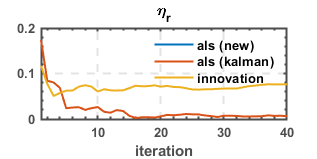

fig = figure; ax = axes(fig);
set(gcf, 'Units', 'centimeters'); set(gcf, 'Position', [0, 0, 12, 6]);
% plot
plot(ax, analy_corrr.');
legend(ax, legend_name, FontName = 'Arial', FontSize=font_size, FontWeight='bold', Location='northeast', Box='off');
xlabel(ax, 'iteration', FontSize=font_size, FontWeight='bold', FontName='Arial', Rotation=0);
title(ax, '\eta_r', FontSize=font_size, FontWeight='bold', FontName='Arial');
% decoration
betterFig(fig, font_size, line_width);
exportgraphics(fig, 'results\mimo_correlation.eps')

函数

function betterFig(fig, font_size, line_width)
    % 寻找axes
    child_axes = findobj(fig.Children, 'type', 'Axes');
    for iter_axes = 1:length(child_axes)
        % 优化格式
        plotAux(child_axes(iter_axes), font_size, line_width);
        % 寻找line
        child_line = findobj(child_axes(iter_axes), 'type', 'Line');
        for iter_line = 1:length(child_line)
            plotAux(child_line(iter_line), font_size, line_width);
        end
    end
end